# Cinemática directa DH

 En este archivo se desarrolla la función encargada de calcular la cinemática directa por el método DH. Con esta función queremos saber la posición en la que se encontrará el efector del robot dados los ángulos de sus articulaciones.

La función será definida como:

*function [x, y] = cinematcia_DH(q1_grados, q2_grados)*

## *Entradas*

**q1_grados** - Posición del servo q1 en grados

**q2_grados **- Posición del servo q2 en grados

## *Salidas*

**X, Y** - Posición en el plano del efector del robot.

## *Parámetros*

**L1, L2** - Longitudes de cada brazo.

function [x, y] = cinematica_DH(q1_grados, q2_grados) % Definición de la cabecera de la función

  Hay que declarar las longitudes de cada brazo en cm.

    L1 = 7.5; 
    L2 = 14.0;

## Conversión a Radianes

Matlab funciona con radianes, mientras que el mensaje a los servos se manda en grados. Por ello, hay que convertir las variables articulares de grados a radianes.

    q1 = deg2rad(q1_grados);
    q2 = deg2rad(q2_grados);

## Implementación de la cinemática

***1 Creamos vectores con los parámetros DH para cada matriz.***

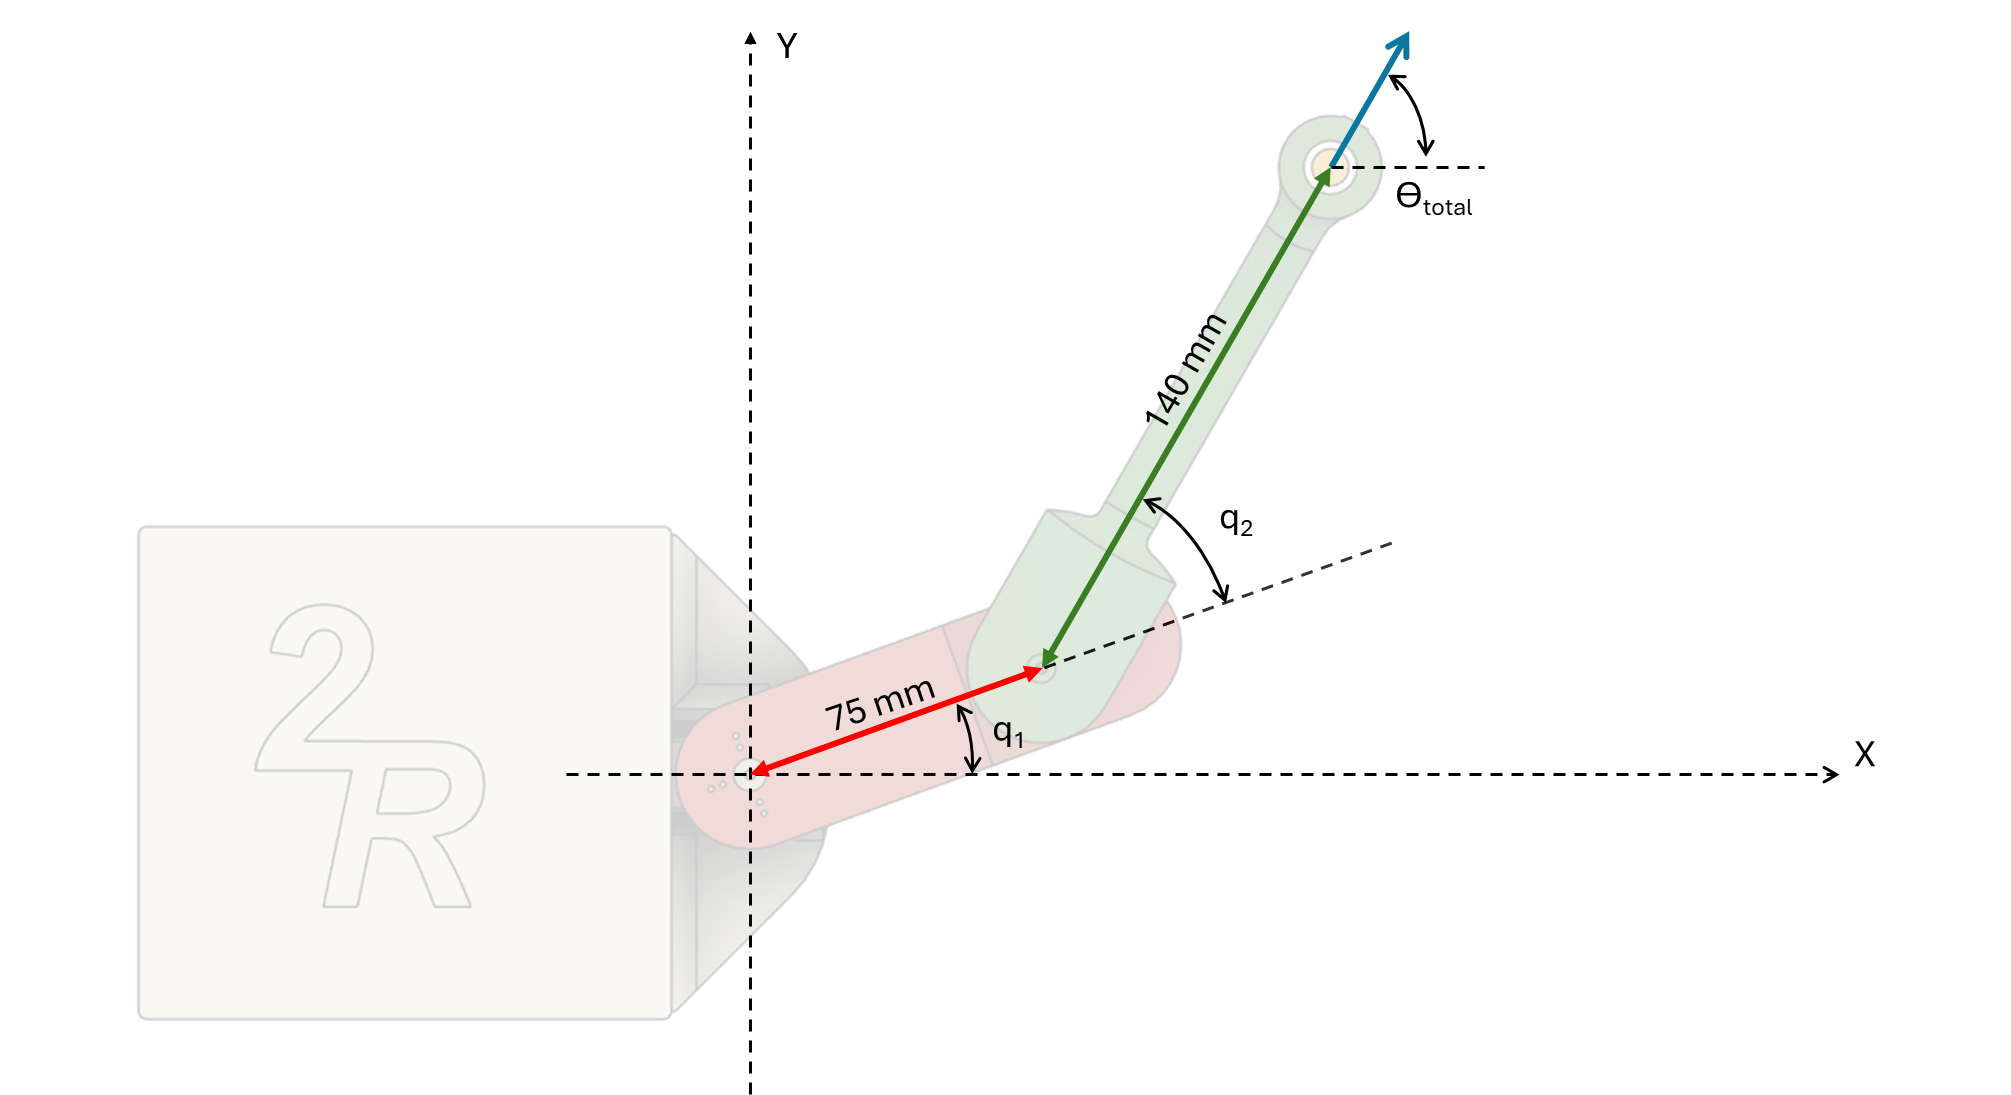

Este vector guardará los parámetros de DH de la siguiente forma:

- 
$${\textrm{dh}}_- \textrm{params}=\left\lbrack \theta ,\;d,\;a,\;\alpha \right\rbrack$$


Como tenemos dos articulaciones, hay que definir un vector con dichos parámetros para cada articulación.  Serán los parámetros que definan la matriz 0-1 y 1-2.

    dh01_params = [q1, 0, L1, 0];
    dh12_params = [q2, 0, L2, 0];

***2 Calculamos las matrices DH01, DH12 y DH02***

Para ello se proporciona en este archivo una función que toma como entradas los parámetros de DH y crea las matrices correspondientes. 

- *T = calcular_matriz_dh(theta, d, a, alpha)*

    % T01: De Base a Eslabón 1
    T01 = calcular_matriz_dh(dh01_params(1), dh01_params(2), dh01_params(3), dh01_params(4));
    
    % T12: De Eslabón 1 a Eslabón 2
    T12 = calcular_matriz_dh(dh12_params(1), dh12_params(2), dh12_params(3), dh12_params(4));

Para obtener la matriz DH02, hay que multiplicar la matriz T01 por la T12.

    T_total = T01 * T12;  

***4 Extraemos el valor de [x, y] de la matriz resultante.***

La posición se encuentra en la 4 columna. De esta extraemos la primera y la segunda fiila.

La matriz resultante será una 4x4, solo nos interesan las posiciones que muestran la translación en el plano XY es decir $p_x$ y $p_y$.


$$T_{\mathrm{total}} =\;\left\lbrack \begin{array}{cccc}
n_x  & o_x  & a_x  & {\mathit{\mathbf{p}}}_{\mathit{\mathbf{x}}} \\
n_y  & o_y  & a_y  & {\mathit{\mathbf{p}}}_{\mathit{\mathbf{y}}} \\
n_z  & o_z  & a_z  & p_z \\
0 & 0 & 0 & 1
\end{array}\right\rbrack ;\;p_x =T_{\mathrm{total}} \left(1,\;4\right);p_y =T_{\mathrm{total}} \left(2,\;4\right)$$


    x = T_total(1, 4); 
    y = T_total(2, 4);
end

## Función para crear matrices DH

function T = calcular_matriz_dh(theta, d, a, alpha)
    % Implementación de la matriz estándar DH
    T = [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
         sin(theta),  cos(theta)*cos(alpha), -sin(theta)*sin(alpha), a*sin(theta);
         0,           sin(alpha),             cos(alpha),            d;
         0,           0,                      0,                     1];
end